% Aint nothiong but a corn dog, mustand and kjetchupo all the time


In order to fit a polynomial to a data set, there's a few things you need.

First, your data set must have at least 3 points, we'll be working through an example first. 

Consider a data set with 3 points (x,y) at (0, 0), (1.5, 1.5), and (4, 1)

figure()
DataPoints = [0,0; 1.5,1.5;4,1]

DataPoints =          0         0
    1.5000    1.5000
    4.0000    1.0000


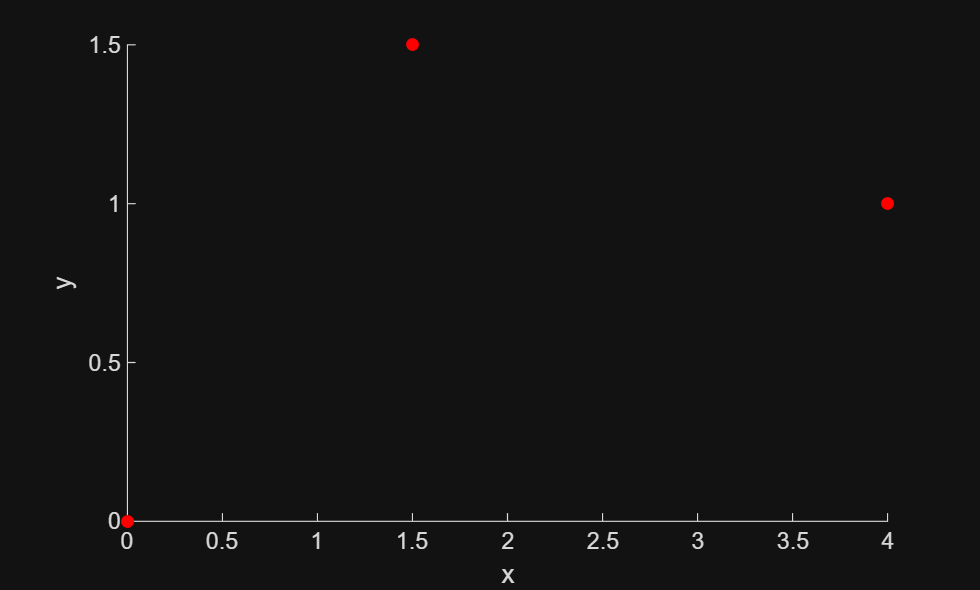

scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
xlabel('x')
ylabel('y')

We want to find a polynomial function that passes through all these points. The most direct way to do this will be with an Nth order polynomial, where N is 1 less than the number of points we wish to pass through; In this case, it will be a 2nd order polynomial (quadratic) since we have 3 points to pass through. The polynomial that we find should take the form: 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


Where N is the degree of the polynomial and 1 less than the number of points we are trying to fit and each a is a coefficient.

The first step to fit the polynomial is to write out the polynomial at each of the N+1 points:


$$f\left(x_1 \right)=a_0 +a_1 x_1 +a_2 {x_1 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_1 }^N$$



$$f\left(x_2 \right)=a_0 +a_1 x_2 +a_2 {x_2 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_2 }^N$$



$$f\left(x_3 \right)=a_0 +a_1 x_3 +a_2 {x_3 }^2 +\;\ldotp \ldotp \ldotp \;a_N {x_3 }^N$$


We can represent this in MATLAB through the use of matrices and vectors


$$\left\lbrack \begin{array}{c}
f\left(x_1 \right)\\
f\left(x_2 \right)\\
f\left(x_3 \right)\\
\ldotp \ldotp \ldotp \\
f\left(x_{N+1} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_1  & x_1^2  &  & x_1^N \\
1 & x_2  & x_2^2  & \ldotp \ldotp \ldotp  & x_2^N \\
1 & x_3  & x_3^2  &  & x_3^N \\
 & \ldotp \ldotp \ldotp  &  & \ldotp \ldotp \ldotp  & \\
1 & x_{N+1}  & x_{N+1}^2  &  & x_{N+1}^N 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack$$


This can be written more simply as:


$$\left\lbrack f\right\rbrack =\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack$$


or


$$\left\lbrack X\right\rbrack \left\lbrack a\right\rbrack =\left\lbrack f\right\rbrack$$


We can now solve for [a] in order to find our polynomial coefficients.


$$\begin{array}{l}
\left\lbrack a\right\rbrack ={\left\lbrack X\right\rbrack }^{-1} \left\lbrack f\right\rbrack \\
\left\lbrack a\right\rbrack =\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_N 
\end{array}\right\rbrack 
\end{array}$$


Let's do that for our example data:

x_Coords = DataPoints(:,1);
f = DataPoints(:,2)

f =          0
    1.5000
    1.0000


X = [1, x_Coords(1), x_Coords(1)^2;
     1, x_Coords(2), x_Coords(2)^2;
     1, x_Coords(3), x_Coords(3)^2]

X =     1.0000         0         0
    1.0000    1.5000    2.2500
    1.0000    4.0000   16.0000


a = X\f

a =          0
    1.4500
   -0.3000


Once we have our a coefficients, we just write the polynomial in the form we determined earlier and we have our function! 


$$f\left(x\right)=a_0 +a_1 x+a_2 x^2 +\;\ldotp \ldotp \ldotp \;a_N x^N$$


ApproxFunc = @(x) 0 + 1.45*x - .3*x^2;
disp('f(x) = 0 + 1.45x - .3x^2')

f(x) = 0 + 1.45x - .3x^2


% We can then plot this against our data to verify that everything fits
% correctly.
figure()
hold on
fplot(ApproxFunc,[0,4])

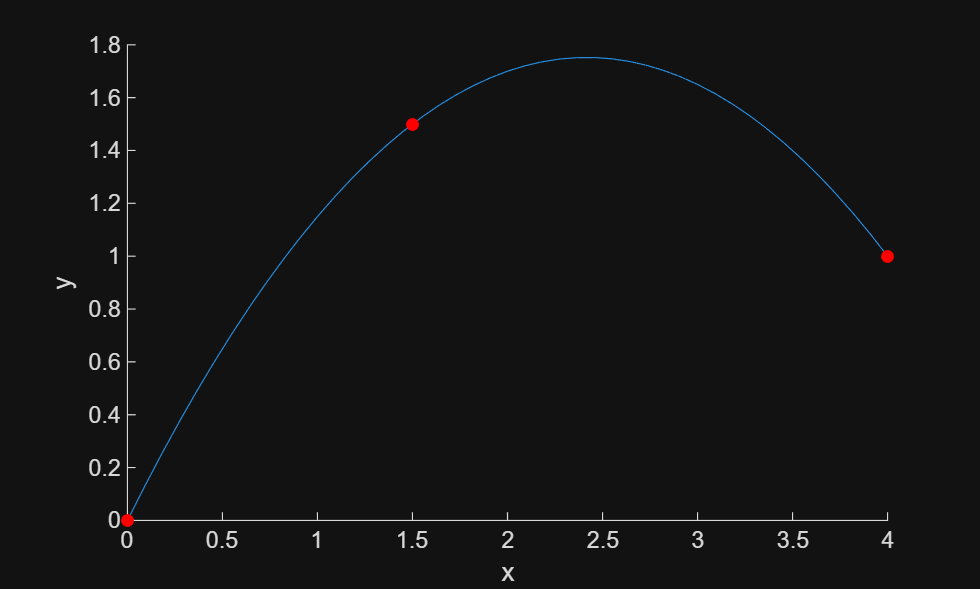

scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
hold off
xlabel('x')
ylabel('y')

% Fit looks Good!

This is all well and good but it can take a long time for large sets of data. Thankfully, MATLAB has the polyfit function that will allow us to do this faster. The syntax for the polyfit function is as follows:

[Coefficients] = polyfit(x, y, n)

Where:

 x is a vector containing the independent data points (the x coordinate of your data points)

y is a vector containing the dependent data points (the y coordinate of your data points; Must be the same size as x)

n is a scalar quantity that denotes the degree of your desired polynomial

[Coefficients] will be a vector of size n+1 and will contain the polynomial coefficients in order of DECREASING degree ($\left.x^3 ,x^2 ,x,\mathrm{etc}\ldotp \right)$

Let's give the polyfit function a try with the same data we had previously:

DataPoints = [0,0; 1.5,1.5;4,1]

DataPoints =          0         0
    1.5000    1.5000
    4.0000    1.0000


x_Coords = DataPoints(:,1);
y_Coords = DataPoints(:,2);
x_Range = 0:.1:max(x_Coords)

x_Range =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


% We can notably choose whatever degree we want for the polyfit function,
% let's choose 2 this time for the sake of simplicity.
Coefficients = polyfit(x_Coords,y_Coords,2)

Coefficients =    -0.3000    1.4500    0.0000


% These are the same coefficents we received earlier, albeit in a different
% order. This arrangement is generally better since it is the standard way
% in which polynomial functions are written.

We can now take these coefficients and use the polyval function to generate a polynomial that we can graph:

FittedLine = polyval(Coefficients,x_Range)

FittedLine =     0.0000    0.1420    0.2780    0.4080    0.5320    0.6500    0.7620    0.8680    0.9680    1.0620    1.1500    1.2320    1.3080    1.3780    1.4420    1.5000    1.5520    1.5980    1.6380    1.6720    1.7000    1.7220    1.7380    1.7480    1.7520    1.7500    1.7420    1.7280    1.7080    1.6820    1.6500    1.6120    1.5680    1.5180    1.4620    1.4000    1.3320    1.2580    1.1780    1.0920    1.0000


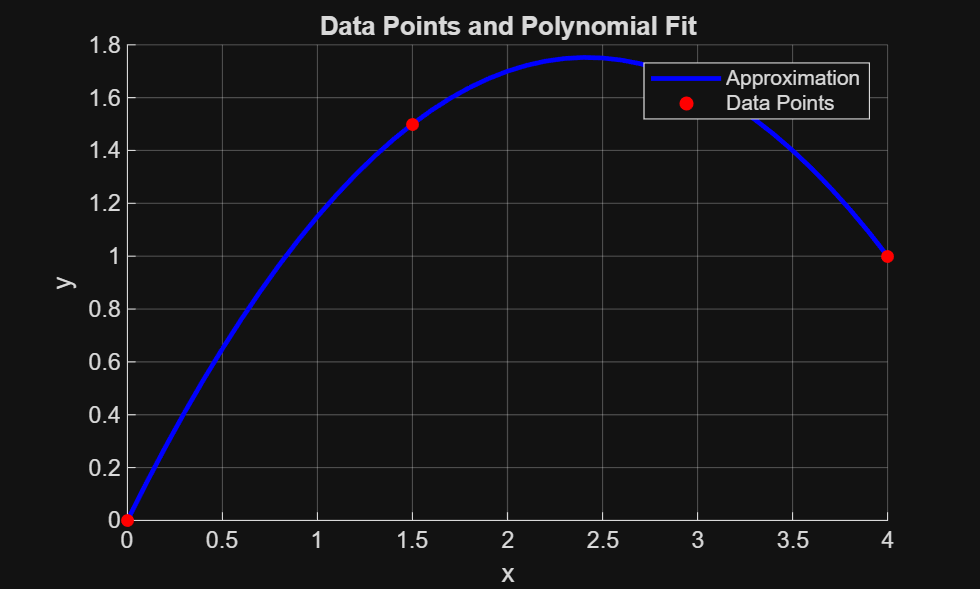

figure()
hold on
plot(x_Range, FittedLine, 'b-', 'LineWidth', 2);
scatter(DataPoints(:,1),DataPoints(:,2), 30, 'r',"filled")
legend('Approximation', 'Data Points');
title('Data Points and Polynomial Fit');
xlabel('x')
ylabel('y')
grid on;
hold off

[Have them work through an example problem, include assert statements to check accuracy. Mod-Sim Style]

This is all well and good, but as you might have noticed this process can end up taking quite some time. Thankfully MATLAB has a function that does just this called polyfit . Below is an example of the polyfit function in use.

Consider exploring different loss functions

Look at absolute value functions, 

Quadratic checking vs absolute value checking, optimizing fit

Absoluta value base loss function

Chi-Square test, Analysis of Variance, How much variance do you remove from the data, 

heteroscedastic 

Bayesian Inference

Squared loss function fit

vs

Absolute value loss function fit (Mean Absolute Deviation)

Compare the fit and how its impacted by outliers.

For Data Sets

Kaggle

Hugging Face